## SIR Model Equations


$$\Delta SI_t = \beta \times I_t \times S_t \times (1 - \lambda u)\\
\Delta IR_t = \gamma \times I_t \\
\Delta RS_t = \alpha \times R_t \\
S_{t+1} = S_t - \Delta SI_t + \Delta RS_t\\
I_{t+1} = I_t + \Delta SI_t - \Delta IR_t \\
R_{t+1} = R_t + \Delta IR_t - \Delta RS_t\\$$



$$\frac{dS}{dt} = -\beta \times I_t \times S_t + \alpha \times R\\
\frac{dI}{dt} = \beta \times I_t \times S_t \times (1 - \lambda u) - \gamma \times I_t \\
\frac{dR}{dt} = \gamma \times I_t - \alpha \times R_t \\$$


% Initialization
weeks = 150;

s_0 = 99;
i_0 = 30/300000000;
r_0 = 0;

beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.04;
lambda =0.73;

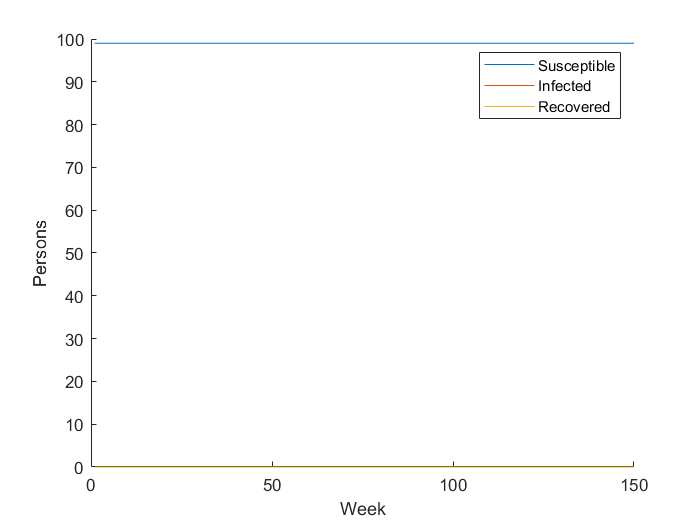

control = 0.7;

% Run simulation
[S, I, R, W] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, control, weeks);

% Plot
figure(1); clf; hold on;
plot(W, S); label1 = "Susceptible";
plot(W, I); label2 = "Infected";
plot(W, R); label3 = "Recovered";

xlabel("Week")
ylabel("Persons")
legend({label1, label2, label3})

% Re-initialization
weeks = 300;

s_0 = 100;
i_0 = 30 / 6500000; % Early covid cases / Massachusetts population
r_0 = 0;

beta = 1 / 90;
gamma = 1 / 2;
alpha = 0.04;
lambda =0.75;

%threshold = 5000 / 6500000; % Massachusetts hospital beds / population
threshold = 1.64;
horizon = 10;
delay = 0;

v_threshold = threshold * (zeros(1, weeks) + 1);

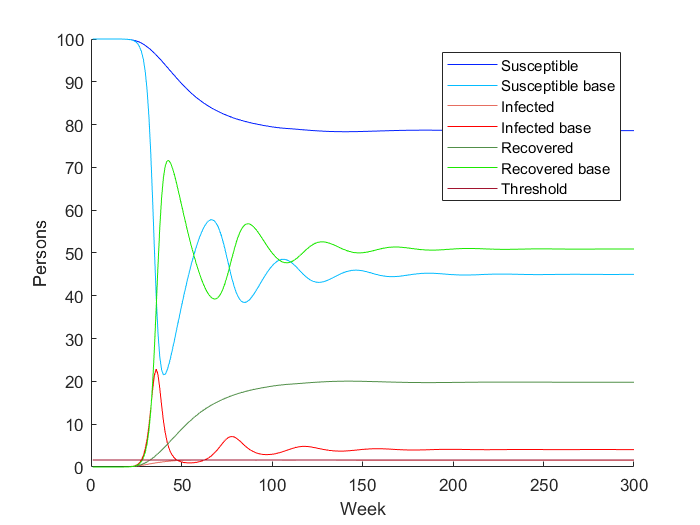

[S_base, I_base, R_base, W_base] = model_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, 0, weeks);
[S, I, R, U, W] = world_simulate(s_0, i_0, r_0, beta, gamma, alpha, lambda, threshold, horizon, delay, weeks);
% Plot
figure(2); clf; hold on;
plot(W, S, 'Color', [5, 34, 255]/255); labelS = "Susceptible";
plot(W, S_base, 'Color', [5, 188, 255]/255); labelS_base = "Susceptible base";

plot(W, I, 'Color', [230, 110, 96]/255); labelI = "Infected";
plot(W, I_base, 'Color', [255, 0, 0]/255); labelI_base = "Infected base";

plot(W, R, 'Color', [81, 143, 73]/255); labelR = "Recovered";
plot(W, R_base, 'Color', [27, 232, 0]/255); labelR_base = "Recovered base";

plot(W, v_threshold); label_threshold = "Threshold";

xlabel("Week")
ylabel("Persons")
% ylim([0, threshold+5])

legend({labelS, labelS_base, labelI, labelI_base, labelR, labelR_base, label_threshold});

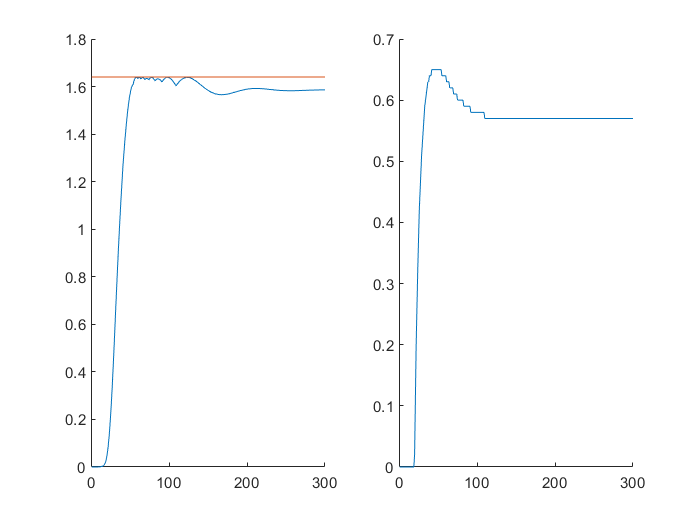

figure(3); clf; 
subplot(1, 2, 1);
hold on;
plot(W, I); labelI = "Infected";
plot(W, v_threshold); labelT = "Threshold";
hold off;

subplot(1, 2, 2);
hold on
plot(W, U); labelU = "Control";